# Paper2 Fig3: investigate smearing

## Setting up WS

CurrentFolder = pwd
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2

addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

close all

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large','Larger','LARGER'};


Choose from the list, but input can take everything between 0-180

AngleInpt = 15;% has to be multiples of 7.5
RotInd = floor(AngleInpt/45); % 0-3
MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
switch MirInd % find the corresponding source
    case 0
        AngSource = mod(AngleInpt,45);
    case 1
        AngSource = mod(-AngleInpt,45);
end
MirInd = logical(MirInd);
% Use the source, decide which response function for angle should I use
AngFuncCtgrCdid = 0:7.5:22.5;
[~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));

AngPrint = AngleList{AngFuncCtgr};
Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

load all precomputed domains

L4EmeshXAll = cell(size(DomList));
L4ImeshYAll = cell(size(DomList));
LDEFrfuncAll = cell(size(DomList));
for DomInd = 1:length(DomList)
    FuncTemp = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{DomInd}),...
        'LDEFrfunc','L4EmeshX','L4ImeshY');
    L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
    L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
    LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
end

% Large = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{2}),...
%     'LDEFrfunc','L4EmeshX','L4ImeshY');
% % L4EmeshXLarge = Large.L4EmeshX;
% % L4ImeshYLarge = Large.L4ImeshY;
% % LDEFrfuncLarge = Large.LDEFrfunc;
%
% Small = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{1}),...
%     'LDEFrfunc','L4EmeshX','L4ImeshY');
% % L4EmeshXSmall = Small.L4EmeshX;
% % L4ImeshYSmall = Small.L4ImeshY;
% % LDEFrfuncSmall = Small.LDEFrfunc;
%
% L4EmeshXAll = {Small.L4EmeshX, Large.L4EmeshX};
% L4ImeshYAll = {Small.L4ImeshY, Large.L4ImeshY};
% LDEFrfuncAll = {Small.LDEFrfunc, Large.LDEFrfunc};

## 3. Set up initial conditions

N_HCOut = 4; NPixX = 10; NPixY = 10;


%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

ICData = load([DataFolder2 sprintf('LDETracesV4D2_New_ang0.0.mat')]);

LDEICPart = ICData.LDEOutAll{1}{end};
LDEICPart = HCRot(LDEICPart,0,N_HCOut,NPixX,NPixY,0);

ICUse = LDEICPart;
IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);

load equiv

%PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
%LDEEquv = PlotUse.LDEEquv;
%LDEEquv = HCRot(LDEEquv,RotInd,N_HCOut,NPixX,NPixY,MirInd);

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
LGNlist = 4; L6list = 4;

LGN and L6 are blurred 

## Note: This small subsec is unused. And should be cos instead of sin

Grating = Angle; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
LGNS_biphase = [45+abs(mod(GratingHC,180)-90)/2;
    45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;

FigOn = true;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;
L6C_Drive_Grating = L6Ord_F_Grating*NC_L6/1e3 * StimulusFac; % only for investigation purpose

smFctL6List = 0.05:0.05:0.8;
smFctLGNList = 0.05:0.05:0.8;
TruncL6 = 1.25; TruncLGN = 1;
EquvAll = cell(length(smFctL6List),length(smFctLGNList));
for L6smInd = 1:length(smFctL6List)
    parfor LGNsmInd = 1:length(smFctLGNList)
        LDEOutAll = cell(size(LDEICPart));
        smFctL6 = smFctL6List(L6smInd);
        smFctLGN = smFctLGNList(LGNsmInd);
        L6smear = n_S_HC*smFctL6; LGNsmear = n_S_HC*smFctLGN;
        
        L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
            N_HC,n_S_HC,L6smear,TruncL6,FigOn);
        LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
            N_HC,n_S_HC,LGNsmear,TruncLGN,FigOn);
        
        PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
        PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

        for Ctgr = 1:4
            PixL6Ctgr(:,Ctgr) = HCRot(PixL6Ctgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
            PixLGNCtgr(:,Ctgr) = HCRot(PixLGNCtgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
        end
        
        PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
        for PixInd = 1:PixNumOut
            PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
        end

Get pixelwise connectivities

        C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

start iteration

        p = 0.33;% 1-p for the original input
        EpocTest = 50;
        ExportFlag = 'xn';
        
        tic
        for TestInd = 1:length(LDEICPart)
                       
            [LDEOutAll{TestInd},~,~,~,~,FuncUse] = ...
                LDEIteration_16FuncMain_CombDom(...
                PixInptCtgrUse,IniTest,p,EpocTest,...
                C_SS_mean,C_CS_mean,C_IS_mean,...
                C_SC_mean,C_CC_mean,C_IC_mean,...
                C_SI_mean,C_CI_mean,C_II_mean,...
                L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
                N_HCOut,NPixX,NPixY,false,'xn')  ;
            LDEEquv = LDEOutAll{TestInd}{end};
        end
        toc
        EquvAll{L6smInd,LGNsmInd} = LDEEquv;
        % save([DataFolder2 sprintf('LDETracesV4D2_New_ang%s.mat',AngPrint)],...
        %     'LDEOutAll','LDEEquv','L2Diff_OneStepAll','DiffVecAll')
    end
end
save(sprintf('smeartest_L6Trc_%.2f.mat',TruncL6),'EquvAll')

## 4. Make Fig3

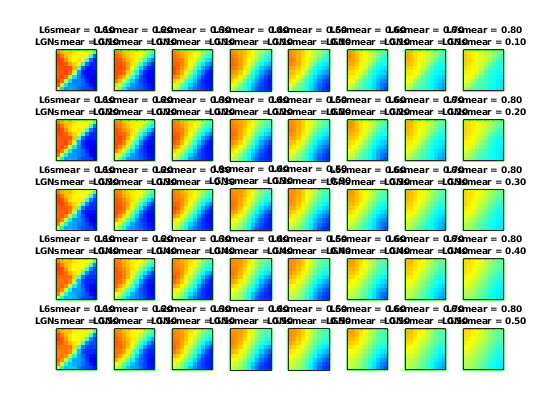

load(sprintf('smeartest_L6Trc_%.2f.mat',TruncL6),'EquvAll')
Fig3 = figure("Name",sprintf('%.1f',AngleInpt));
%figure('Name','Fig3_EpocScan','units','normalized','outerposition',[-1,0,0.5,0.4]);

L6List = 2:2:16;
LGNList = 2:2:10;
Panel1 = length(L6List); Panel2 = length(LGNList);%length(EpocList);
ha = tight_subplot(Panel2,Panel1,[.03 .03],[.1 .1],[.10 .10]);
plotind = 1;
for LGNsmInd = 1:length(LGNList)
    for L6smInd = 1:length(L6List)
        LDEPlot = EquvAll{L6List(L6smInd),LGNList(LGNsmInd)};
        axes(ha(plotind));
        
        titleprt = sprintf('L6smear = %.2f\nLGNsmear = %.2f',...
            smFctL6List(L6List(L6smInd)), smFctLGNList(LGNList(LGNsmInd)));
        ShowField(...
            LDEPlot.S*(1-CplxR)+LDEPlot.C*CplxR,...
            1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
            titleprt, [5 35]) % last input may catgorized cbar: ,, [5 60]
        set(gca,'fontsize',6)
        set(gca,'YTickLabel',[]);
        set(gca,'XTickLabel',[]);
        colorbar off
        axis([NPixX+.5 2*NPixX+.5 NPixX+.5 2*NPixY+.5])
        plotind = plotind+1;
    end
end



    %subplot(2,6,EpocInd+6*(ICInd-1))
    

